# X-Opgave 4.25

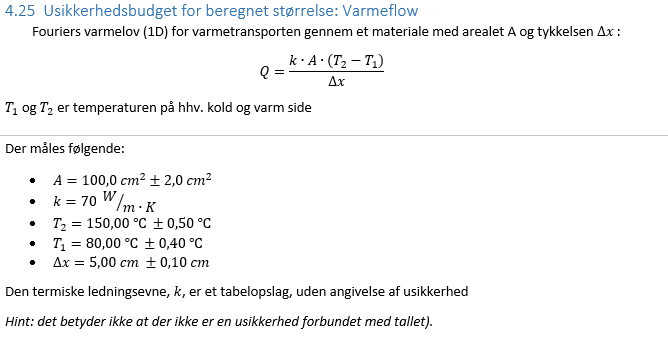

## Opgave A

**Arealet **antages at være trekant fordelt, da en plades $l_1
$ og $l_2
$ kunne måles som en firkant fordelt variabel i begge ender. Den ene kunne variere lidt mere i bredde i den ene ende, og det samme med længden

**Den termiske ledeevne **antages at være trekantsfordelt, efter tabelopslag for vands varme konduktivitet, der stiger fra lave til mellem temperaturer, og falder derefter igen ved de højere temperaturer

**Temperaturene **antages at være firkantfordelte, da det antages at være hårde grænser, hvori målingsudfald vil være højst usandsynlige at finde

**Tykkelsen **antages at være U-fordelt, da vi lader som om at pladens tykkelse forløb følger den termiske ledeevnes forløb inverst, så er tyk ved lav tem, skrumper til middel temp, og udvider sig igen ved høj temp (håber det er acceptabelt digteri)

## Opgave b

clc; clear all;
u = symunit;

syms  alpha

% Usikkerhedsformler
u_f = alpha/sqrt(3)

$$u\_f = \frac{\sqrt{3}\,\alpha }{3}$$

u_t = alpha/sqrt(6)

$$u\_t = \frac{\sqrt{6}\,\alpha }{6}$$

u_u = alpha/sqrt(2)

$$u\_u = \frac{\sqrt{2}\,\alpha }{2}$$



% Værdier
C = 273.15;

A = 100*u.cm^2;
k = 70 * u.W/(u.m*u.K);
T1 = (80)*u.K;
T2 = (150)*u.K;
x = 5*u.cm;
var_list = [A T1 T2 x k]

$$var\_list = \left(\begin{array}{ccccc} 100\,{\mathrm{cm}}^{2} & 80\,K & 150\,K & 5\,\mathrm{cm} & 70\,\frac{W}{K\,m} \end{array}\right)$$


% Usikkerheder
Au = 2*u.cm^2;
ku = 1 * u.W/(u.m*u.K); % antaget usikkerhed
T1u = 0.4*u.K;
T2u = 0.5*u.K;
xu = 0.1* u.cm;

% Fordelingsusikkerheder
f_Au = subs(u_t, alpha, Au);
f_ku = subs(u_t, alpha, ku);
f_T1u = subs(u_f, alpha, T1u);
f_T2u = subs(u_f, alpha, T2u);
f_xu = subs(u_u, alpha, xu);

f_list = vpa([f_Au, f_T1u,f_T2u,f_xu,0],3)

$$f\_list = \left(\begin{array}{ccccc} 0.816\,{\mathrm{cm}}^{2} & 0.231\,K & 0.289\,K & 0.0707\,\mathrm{cm} & 0 \end{array}\right)$$

## Opgave c

syms k A T_2 T_1 delta_x
Q = (k*A*(T_2 - T_1))/delta_x

$$Q = -\frac{A\,k\,\left(T_{1}-T_{2}\right)}{\delta_{x}}$$


vars = symvar(Q)

$$vars = \left(\begin{array}{ccccc} A & T_{1} & T_{2} & \delta_{x} & k \end{array}\right)$$

% Værdier
C = 273.15;

A = 100*u.cm^2;
k = 70 * u.W/(u.m*u.K);
T1 = (80)*u.K;
T2 = (150)*u.K;
x = 5*u.cm;
var_list = [A T1 T2 x k]

$$var\_list = \left(\begin{array}{ccccc} 100\,{\mathrm{cm}}^{2} & 80\,K & 150\,K & 5\,\mathrm{cm} & 70\,\frac{W}{K\,m} \end{array}\right)$$


% Usikkerheder
Au = 2*u.cm^2;
ku = 0.5 * u.W/(u.m*u.K); % antaget usikkerhed
T1u = 0.4*u.K;
T2u = 0.5*u.K;
xu = 0.1* u.cm;

% Fordelingsusikkerheder
f_Au = subs(u_t, alpha, Au);
f_ku = subs(u_t, alpha, ku);
f_T1u = subs(u_f, alpha, T1u);
f_T2u = subs(u_f, alpha, T2u);
f_xu = subs(u_u, alpha, xu);

f_list = vpa([f_Au, f_T1u,f_T2u,f_xu,f_ku],3)

$$f\_list = \left(\begin{array}{ccccc} 0.816\,{\mathrm{cm}}^{2} & 0.231\,K & 0.289\,K & 0.0707\,\mathrm{cm} & 0.204\,\frac{W}{K\,m} \end{array}\right)$$


U = Opbhobningsloven(Q, vars, var_list, f_list)

$$U = 1706.0480649896977154431789643592\,\frac{W\,\mathrm{cm}}{m}$$




vpa(unitConvert(U,u.W),3)

$$ans = 17.1\,W$$